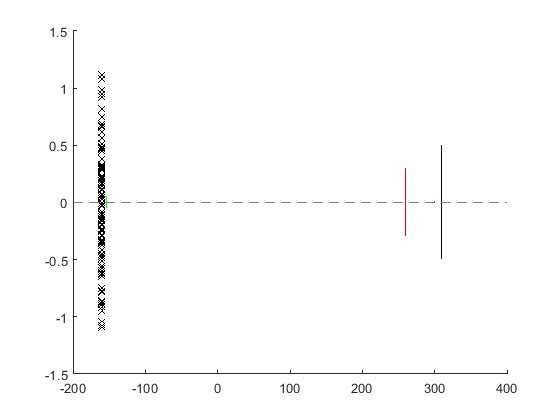

addpath("functionsAndGUI\");
%clear all;

%plot setup with
beamon=false;

%Goebel specification
NRays=1E3; %number of rays per source
Ngoebel=1E2 ; %Number of sources on Goebel mirror

delta=0.03; %divergence angle
fwhm=1.35; %fwhm of Goebel source distr.
ds=160; %distance to sources on sarm
dgoebelsslit=7; %distance Goebel to source slit
gammas=90; %Goebel mirror rotation [deg] (90=not rotated)



%slit specifications
wsslit=0.1; %width source slit
wantisc=0.6; %width anti-scatter slit
wdslit=0.01; %width detector slit
dantisc=260; %distance antiscatter slit on darm
ddslit=300; %distance detector slit on darm

%sample specifications
wsample=10;
offset=0;
gammasample=0;

%detector speficications
dd=310;
wd=1;
NPixels=100;

%Height Scan specifications
alpha=0; %Source arm angle
beta=0; %detector arm angle
h_min=-0.15;
h_max=0.15;
incr=0.002;




%items calculations
gammasslit=90; gammadslit=90; gammaantisc=90; gammad=90;
dsslit=ds-dgoebelsslit;

%Create setup
setup=startsetup();

setup=add_goebel(setup,ds,gammas,fwhm,Ngoebel,NRays,delta);
setup=add_sslit(setup,dsslit,wsslit, gammasslit);
setup=add_sample(setup,wsample,offset,gammasample);
setup=add_dslit(setup,dantisc,wantisc,gammaantisc);
setup=add_dslit(setup,ddslit,wdslit,gammadslit);
setup=add_detector(setup,dd,wd, gammad,NPixels);


%plot basic, non-rotated setup with beams off or on depending on beamon
fig1=plot_setup(setup,0,0,beamon,dd+1);


%Height Scan
[h,J]=Scan_Height(setup,h_min,h_max,incr,alpha,beta);

ans =    -5.0000
   -0.1500


ans =     5.0000
   -0.1500


ans = -0.1500

ans =    -5.0000
   -0.1480


ans =     5.0000
   -0.1480


ans = -0.1480

ans =    -5.0000
   -0.1460


ans =     5.0000
   -0.1460


ans = -0.1460

ans =    -5.0000
   -0.1440


ans =     5.0000
   -0.1440


ans = -0.1440

ans =    -5.0000
   -0.1420


ans =     5.0000
   -0.1420


ans = -0.1420

ans =    -5.0000
   -0.1400


ans =     5.0000
   -0.1400


ans = -0.1400

ans =    -5.0000
   -0.1380


ans =     5.0000
   -0.1380


ans = -0.1380

ans =    -5.0000
   -0.1360


ans =     5.0000
   -0.1360


ans = -0.1360

ans =    -5.0000
   -0.1340


ans =     5.0000
   -0.1340


ans = -0.1340

ans =    -5.0000
   -0.1320


ans =     5.0000
   -0.1320


ans = -0.1320

ans =    -5.0000
   -0.1300


ans =     5.0000
   -0.1300


ans = -0.1300

ans =    -5.0000
   -0.1280


ans =     5.0000
   -0.1280


ans = -0.1280

ans =    -5.0000
   -0.1260


ans =     5.0000
   -0.1260


ans = -0.1260

ans =    -5.0000
   -0.1240


ans =     5.0000
   -0.1240


ans = -0.1240

ans =    -5.0000
   -0.1220


ans =     5.0000
   -0.1220


ans = -0.1220

ans =    -5.0000
   -0.1200


ans =     5.0000
   -0.1200


ans = -0.1200

ans =    -5.0000
   -0.1180


ans =     5.0000
   -0.1180


ans = -0.1180

ans =    -5.0000
   -0.1160


ans =     5.0000
   -0.1160


ans = -0.1160

ans =    -5.0000
   -0.1140


ans =     5.0000
   -0.1140


ans = -0.1140

ans =    -5.0000
   -0.1120


ans =     5.0000
   -0.1120


ans = -0.1120

ans =    -5.0000
   -0.1100


ans =     5.0000
   -0.1100


ans = -0.1100

ans =    -5.0000
   -0.1080


ans =     5.0000
   -0.1080


ans = -0.1080

ans =    -5.0000
   -0.1060


ans =     5.0000
   -0.1060


ans = -0.1060

ans =    -5.0000
   -0.1040


ans =     5.0000
   -0.1040


ans = -0.1040

ans =    -5.0000
   -0.1020


ans =     5.0000
   -0.1020


ans = -0.1020

ans =    -5.0000
   -0.1000


ans =     5.0000
   -0.1000


ans = -0.1000

ans =    -5.0000
   -0.0980


ans =     5.0000
   -0.0980


ans = -0.0980

ans =    -5.0000
   -0.0960


ans =     5.0000
   -0.0960


ans = -0.0960

ans =    -5.0000
   -0.0940


ans =     5.0000
   -0.0940


ans = -0.0940

ans =    -5.0000
   -0.0920


ans =     5.0000
   -0.0920


ans = -0.0920

ans =    -5.0000
   -0.0900


ans =     5.0000
   -0.0900


ans = -0.0900

ans =    -5.0000
   -0.0880


ans =     5.0000
   -0.0880


ans = -0.0880

ans =    -5.0000
   -0.0860


ans =     5.0000
   -0.0860


ans = -0.0860

ans =    -5.0000
   -0.0840


ans =     5.0000
   -0.0840


ans = -0.0840

ans =    -5.0000
   -0.0820


ans =     5.0000
   -0.0820


ans = -0.0820

ans =    -5.0000
   -0.0800


ans =     5.0000
   -0.0800


ans = -0.0800

ans =    -5.0000
   -0.0780


ans =     5.0000
   -0.0780


ans = -0.0780

ans =    -5.0000
   -0.0760


ans =     5.0000
   -0.0760


ans = -0.0760

ans =    -5.0000
   -0.0740


ans =     5.0000
   -0.0740


ans = -0.0740

ans =    -5.0000
   -0.0720


ans =     5.0000
   -0.0720


ans = -0.0720

ans =    -5.0000
   -0.0700


ans =     5.0000
   -0.0700


ans = -0.0700

ans =    -5.0000
   -0.0680


ans =     5.0000
   -0.0680


ans = -0.0680

ans =    -5.0000
   -0.0660


ans =     5.0000
   -0.0660


ans = -0.0660

ans =    -5.0000
   -0.0640


ans =     5.0000
   -0.0640


ans = -0.0640

ans =    -5.0000
   -0.0620


ans =     5.0000
   -0.0620


ans = -0.0620

ans =    -5.0000
   -0.0600


ans =     5.0000
   -0.0600


ans = -0.0600

ans =    -5.0000
   -0.0580


ans =     5.0000
   -0.0580


ans = -0.0580

ans =    -5.0000
   -0.0560


ans =     5.0000
   -0.0560


ans = -0.0560

ans =    -5.0000
   -0.0540


ans =     5.0000
   -0.0540


ans = -0.0540

ans =    -5.0000
   -0.0520


ans =     5.0000
   -0.0520


ans = -0.0520

ans =    -5.0000
   -0.0500


ans =     5.0000
   -0.0500


ans = -0.0500

ans =    -5.0000
   -0.0480


ans =     5.0000
   -0.0480


ans = -0.0480

ans =    -5.0000
   -0.0460


ans =     5.0000
   -0.0460


ans = -0.0460

ans =    -5.0000
   -0.0440


ans =     5.0000
   -0.0440


ans = -0.0440

ans =    -5.0000
   -0.0420


ans =     5.0000
   -0.0420


ans = -0.0420

ans =    -5.0000
   -0.0400


ans =     5.0000
   -0.0400


ans = -0.0400

ans =    -5.0000
   -0.0380


ans =     5.0000
   -0.0380


ans = -0.0380

ans =    -5.0000
   -0.0360


ans =     5.0000
   -0.0360


ans = -0.0360

ans =    -5.0000
   -0.0340


ans =     5.0000
   -0.0340


ans = -0.0340

ans =    -5.0000
   -0.0320


ans =     5.0000
   -0.0320


ans = -0.0320

ans =    -5.0000
   -0.0300


ans =     5.0000
   -0.0300


ans = -0.0300

ans =    -5.0000
   -0.0280


ans =     5.0000
   -0.0280


ans = -0.0280

ans =    -5.0000
   -0.0260


ans =     5.0000
   -0.0260


ans = -0.0260

ans =    -5.0000
   -0.0240


ans =     5.0000
   -0.0240


ans = -0.0240

ans =    -5.0000
   -0.0220


ans =     5.0000
   -0.0220


ans = -0.0220

ans =    -5.0000
   -0.0200


ans =     5.0000
   -0.0200


ans = -0.0200

ans =    -5.0000
   -0.0180


ans =     5.0000
   -0.0180


ans = -0.0180

ans =    -5.0000
   -0.0160


ans =     5.0000
   -0.0160


ans = -0.0160

ans =    -5.0000
   -0.0140


ans =     5.0000
   -0.0140


ans = -0.0140

ans =    -5.0000
   -0.0120


ans =     5.0000
   -0.0120


ans = -0.0120

ans =    -5.0000
   -0.0100


ans =     5.0000
   -0.0100


ans = -0.0100

ans =    -5.0000
   -0.0080


ans =     5.0000
   -0.0080


ans = -0.0080

ans =    -5.0000
   -0.0060


ans =     5.0000
   -0.0060


ans = -0.0060

ans =    -5.0000
   -0.0040


ans =     5.0000
   -0.0040


ans = -0.0040

ans =    -5.0000
   -0.0020


ans =     5.0000
   -0.0020


ans = -0.0020

ans =     -5
     0


ans =      5
     0


ans = 0

ans =    -5.0000
    0.0020


ans =     5.0000
    0.0020


ans = 0.0020

ans =    -5.0000
    0.0040


ans =     5.0000
    0.0040


ans = 0.0040

ans =    -5.0000
    0.0060


ans =     5.0000
    0.0060


ans = 0.0060

ans =    -5.0000
    0.0080


ans =     5.0000
    0.0080


ans = 0.0080

ans =    -5.0000
    0.0100


ans =     5.0000
    0.0100


ans = 0.0100

ans =    -5.0000
    0.0120


ans =     5.0000
    0.0120


ans = 0.0120

ans =    -5.0000
    0.0140


ans =     5.0000
    0.0140


ans = 0.0140

ans =    -5.0000
    0.0160


ans =     5.0000
    0.0160


ans = 0.0160

ans =    -5.0000
    0.0180


ans =     5.0000
    0.0180


ans = 0.0180

ans =    -5.0000
    0.0200


ans =     5.0000
    0.0200


ans = 0.0200

ans =    -5.0000
    0.0220


ans =     5.0000
    0.0220


ans = 0.0220

ans =    -5.0000
    0.0240


ans =     5.0000
    0.0240


ans = 0.0240

ans =    -5.0000
    0.0260


ans =     5.0000
    0.0260


ans = 0.0260

ans =    -5.0000
    0.0280


ans =     5.0000
    0.0280


ans = 0.0280

ans =    -5.0000
    0.0300


ans =     5.0000
    0.0300


ans = 0.0300

ans =    -5.0000
    0.0320


ans =     5.0000
    0.0320


ans = 0.0320

ans =    -5.0000
    0.0340


ans =     5.0000
    0.0340


ans = 0.0340

ans =    -5.0000
    0.0360


ans =     5.0000
    0.0360


ans = 0.0360

ans =    -5.0000
    0.0380


ans =     5.0000
    0.0380


ans = 0.0380

ans =    -5.0000
    0.0400


ans =     5.0000
    0.0400


ans = 0.0400

ans =    -5.0000
    0.0420


ans =     5.0000
    0.0420


ans = 0.0420

ans =    -5.0000
    0.0440


ans =     5.0000
    0.0440


ans = 0.0440

ans =    -5.0000
    0.0460


ans =     5.0000
    0.0460


ans = 0.0460

ans =    -5.0000
    0.0480


ans =     5.0000
    0.0480


ans = 0.0480

ans =    -5.0000
    0.0500


ans =     5.0000
    0.0500


ans = 0.0500

ans =    -5.0000
    0.0520


ans =     5.0000
    0.0520


ans = 0.0520

ans =    -5.0000
    0.0540


ans =     5.0000
    0.0540


ans = 0.0540

ans =    -5.0000
    0.0560


ans =     5.0000
    0.0560


ans = 0.0560

ans =    -5.0000
    0.0580


ans =     5.0000
    0.0580


ans = 0.0580

ans =    -5.0000
    0.0600


ans =     5.0000
    0.0600


ans = 0.0600

ans =    -5.0000
    0.0620


ans =     5.0000
    0.0620


ans = 0.0620

ans =    -5.0000
    0.0640


ans =     5.0000
    0.0640


ans = 0.0640

ans =    -5.0000
    0.0660


ans =     5.0000
    0.0660


ans = 0.0660

ans =    -5.0000
    0.0680


ans =     5.0000
    0.0680


ans = 0.0680

ans =    -5.0000
    0.0700


ans =     5.0000
    0.0700


ans = 0.0700

ans =    -5.0000
    0.0720


ans =     5.0000
    0.0720


ans = 0.0720

ans =    -5.0000
    0.0740


ans =     5.0000
    0.0740


ans = 0.0740

ans =    -5.0000
    0.0760


ans =     5.0000
    0.0760


ans = 0.0760

ans =    -5.0000
    0.0780


ans =     5.0000
    0.0780


ans = 0.0780

ans =    -5.0000
    0.0800


ans =     5.0000
    0.0800


ans = 0.0800

ans =    -5.0000
    0.0820


ans =     5.0000
    0.0820


ans = 0.0820

ans =    -5.0000
    0.0840


ans =     5.0000
    0.0840


ans = 0.0840

ans =    -5.0000
    0.0860


ans =     5.0000
    0.0860


ans = 0.0860

ans =    -5.0000
    0.0880


ans =     5.0000
    0.0880


ans = 0.0880

ans =    -5.0000
    0.0900


ans =     5.0000
    0.0900


ans = 0.0900

ans =    -5.0000
    0.0920


ans =     5.0000
    0.0920


ans = 0.0920

ans =    -5.0000
    0.0940


ans =     5.0000
    0.0940


ans = 0.0940

ans =    -5.0000
    0.0960


ans =     5.0000
    0.0960


ans = 0.0960

ans =    -5.0000
    0.0980


ans =     5.0000
    0.0980


ans = 0.0980

ans =    -5.0000
    0.1000


ans =     5.0000
    0.1000


ans = 0.1000

ans =    -5.0000
    0.1020


ans =     5.0000
    0.1020


ans = 0.1020

ans =    -5.0000
    0.1040


ans =     5.0000
    0.1040


ans = 0.1040

ans =    -5.0000
    0.1060


ans =     5.0000
    0.1060


ans = 0.1060

ans =    -5.0000
    0.1080


ans =     5.0000
    0.1080


ans = 0.1080

ans =    -5.0000
    0.1100


ans =     5.0000
    0.1100


ans = 0.1100

ans =    -5.0000
    0.1120


ans =     5.0000
    0.1120


ans = 0.1120

ans =    -5.0000
    0.1140


ans =     5.0000
    0.1140


ans = 0.1140

ans =    -5.0000
    0.1160


ans =     5.0000
    0.1160


ans = 0.1160

ans =    -5.0000
    0.1180


ans =     5.0000
    0.1180


ans = 0.1180

ans =    -5.0000
    0.1200


ans =     5.0000
    0.1200


ans = 0.1200

ans =    -5.0000
    0.1220


ans =     5.0000
    0.1220


ans = 0.1220

ans =    -5.0000
    0.1240


ans =     5.0000
    0.1240


ans = 0.1240

ans =    -5.0000
    0.1260


ans =     5.0000
    0.1260


ans = 0.1260

ans =    -5.0000
    0.1280


ans =     5.0000
    0.1280


ans = 0.1280

ans =    -5.0000
    0.1300


ans =     5.0000
    0.1300


ans = 0.1300

ans =    -5.0000
    0.1320


ans =     5.0000
    0.1320


ans = 0.1320

ans =    -5.0000
    0.1340


ans =     5.0000
    0.1340


ans = 0.1340

ans =    -5.0000
    0.1360


ans =     5.0000
    0.1360


ans = 0.1360

ans =    -5.0000
    0.1380


ans =     5.0000
    0.1380


ans = 0.1380

ans =    -5.0000
    0.1400


ans =     5.0000
    0.1400


ans = 0.1400

ans =    -5.0000
    0.1420


ans =     5.0000
    0.1420


ans = 0.1420

ans =    -5.0000
    0.1440


ans =     5.0000
    0.1440


Please add source


ans = 0.1440

ans =    -5.0000
    0.1460


ans =     5.0000
    0.1460


Please add source


ans = 0.1460

ans =    -5.0000
    0.1480


ans =     5.0000
    0.1480


Please add source


ans = 0.1480

ans =    -5.0000
    0.1500


ans =     5.0000
    0.1500


Please add source


ans = 0.1500

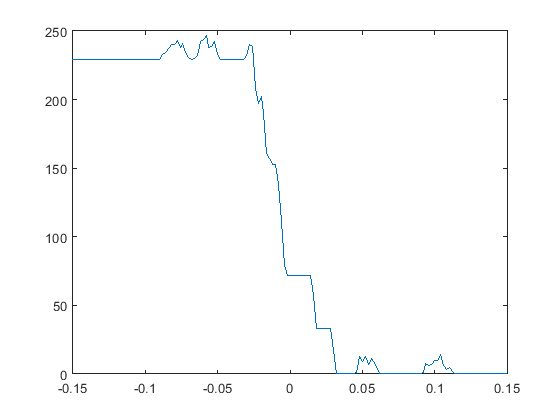

Elapsed time is 2.660847 seconds.


figure;
plot(h,J);